## X-ray transform on $\mathbb{R}^2$

A planar line $\gamma$ is parametrized by $(\theta,t)\in[0,\pi]\times\mathbb{R}$ as 


$$\gamma
=
\gamma(\theta,t)
=
\{
(x,y)\in\mathbb{R}^2
\ : \ 
x\cos\theta+y\sin\theta=t
\}$$



$$\qquad\qquad
=
\{
(x,y)\in\mathbb{R}^2
\ : \ 
\cos\theta(x-t\cos\theta)+\sin\theta(y-t\sin\theta)=0
\}$$



$$\qquad\qquad
=
\{
\vec{x}\in\mathbb{R}^2
\ : \ 
\vec{\omega}\cdot(\vec{x}-t\vec{\omega})=0
\}$$



$$\qquad\qquad
=
\{
(t\cos\theta-s\sin\theta,t\sin\theta+s\cos\theta)
\ : \ 
s\in\mathbb{R}
\}$$


where $\vec{\omega}=(\cos\theta,\sin\theta)$. The X-ray transform of a function $f$ of $(x,y)$ is defined by 


$$\mathcal{R}_1f(\gamma)
=
\mathcal{R}_1f(\theta,t)
:=
\int_\gamma f
=
\int_{-\infty}^\infty f(t\cos\theta-s\sin\theta,t\sin\theta+s\cos\theta)ds, 
\quad
(\theta,t)\in[0,\pi]\times\mathbb{R}.$$
 

Note that $\mathcal{R}_1f(\theta,t)=\mathcal{R}_1f(\theta+\pi,-t)$. 

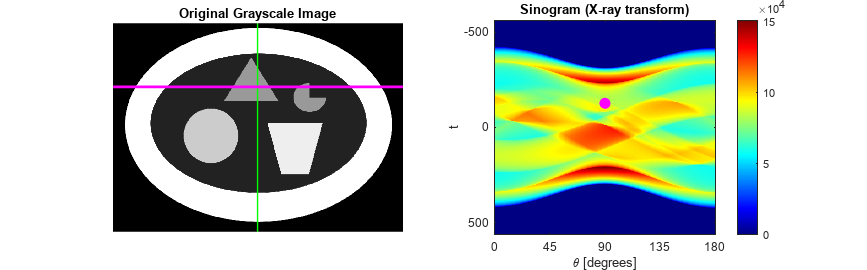

% define f(x,y)
f=imread('stomach.png');
% xray transform of f
rho =0:180;
[Xf,s]=radon(f,rho);
[m,n]=size(Xf);
XXf=zeros(m,n);
for i=1:m
    for j=1:n
        XXf(i,j)=Xf(m-i+1,j);
    end
end

theta =90;  t =127;

% plotting
subplot(1,2,1);
imshow(f);
title('Original Grayscale Image');
hold on
if theta == 90
    plot([456 456], [1 657],'Color','g','LineWidth',1)
    plot([1 914], [328-t 328-t],'Color','magenta','LineWidth',2);
else
    plot([1 914], [328+456*tan(pi*theta/180) 328-456*tan(pi*theta/180)],'Color','g','LineWidth',1)
    plot([457+t/cos(pi*theta/180)-328*tan(pi*theta/180) 457+t/cos(pi*theta/180)+328*tan(pi*theta/180)], [1 657],'Color','magenta','LineWidth',2);
end
hold off
p2=subplot(1,2,2);
imagesc(rho,s,XXf);
title('Sinogram (X-ray transform)');
xlabel('\theta [degrees]');
ylabel('t');
set(gca,'XTick',0:45:180);
colormap(p2,jet);
colorbar;
hold on
sz0=70;
scatter(theta,-t,sz0,'filled','MarkerFaceColor','magenta');
hold off
set(gcf,'Position',[900,200,2500,600]);
saveas(gcf,'xray_stomach1.png');